clc;
clear all;
close all;

#### Loading Data

folders=addpath('data','ESC_functions','SH_functions');
% IRs from empty room
load('dataI_s1r1.mat');
IRwithoutFilter(:,:,1)=data;
% Reference room I: dataI_...
               % s1r1 source position 1 and receiver position 1
               % s2r1 source position 2 and receiver position 1
               % s1r2 source position 1 and receiver position 2
% Reference room II: dataII_...


% IRs from furnished room
load('dataC_s1r1m2.mat');
IRwithoutFilter(:,:,2)=data;
% Test room A: dataA_...
% Test room B: dataB_...           
% Test room C: dataC_...  
               % m1 represent absorption coefficient of furniture is 0.1
               % m2 represent absorption coefficient of furniture is 0.3
               % m3 represent absorption coefficient of furniture is 0.5
% Test room D: dataD_...
% Test room E: dataE_...

#### Basic parameters

% Number of the scenarios
nScenarios=size(IRwithoutFilter,3);
% Speed of sound (m/s)
c0 = 343;
% Sampling frequency (Hz)
fs = 32000;
% Length of the signals
nSamplesSignal=length(data);
% Time vector
tv = (0:1:nSamplesSignal-1) * (1 / fs);
% Max frequency
fMax=2500;
% Which 1/3 octave band to plot
plotOctaveBand=9;
% which receiver to plot
plotReceiver=1;
% Equation to calculate sound pressure level
spl = @(input)(20 * log10(abs(input)))+120;

#### Transducers

% Number of receivers
nReceivers = length(receiverPos);
% Distance from source to receivers
distance = vecnorm(abs(bsxfun(@minus,sourcePos,receiverPos))')';
% Calculate arrival time (s)
tDirectSec = distance ./ c0;
% Calculate arrival time (sampleNo)
nDirectSample = ceil(tDirectSec*fs);

#### To define time window (to chop signals)

% Mean free path length of empty room
meanFreePathLength = 4 * volume ./ surfaceArea;
% Approximate reflection order
order = (1./meanFreePathLength)*tv * c0 ;
% Each short signal contains one reflection 
nReflection = 1;
% Number of short signals
tMax =max(tv);
nSegment = floor(tMax/(nReflection * (meanFreePathLength/ c0)));
% Points of each short signal contains
nChoppedIR = floor(nSamplesSignal/nSegment);
% Time vector for each short signal
tSegment=nChoppedIR*(0.5:nSegment-0.5)/fs;

#### To define filter

% Center frequency of the filter 
centerFrequenciesValid=[315  400  500    630    800   1000   1250    1600   2000];% or use centerFrequencies=getCenterFrequencies(ofb);
% Number of 1/3 octave bands 
nOctaveBands=length(centerFrequenciesValid);
% Filter    
ofb = octaveFilterBank("1/3 octave",fs,FilterOrder=10);
bandpassFilters = freqz(ofb,NFFT=fs/2+1); 
bandpassFiltersValid=bandpassFilters(:,12:20);
% Bandedge frequency 
BandedgeFrequencies=getBandedgeFrequencies(ofb);
BandedgeFrequenciesValid=floor(BandedgeFrequencies(12:21));

#### To filter IRs

for iScenario = 1:nScenarios
for iReceiver = 1:nReceivers
for iOctaveBand = 1:nOctaveBands        
         thisIRfiltered=calculate_filteredSignal(IRwithoutFilter(:,iReceiver,iScenario),bandpassFiltersValid(:,iOctaveBand),nSamplesSignal);
         IRfiltered(iScenario,iReceiver,iOctaveBand,:)=thisIRfiltered;
end 
end
end

#### Wide band IRs

IRsWideBand=reshape(sum(IRfiltered,3),nScenarios,nReceivers,nSamplesSignal);

#### To chop signals

% Max order of the short signal
maxOrder=10;
% Order vector
nOrder=0:maxOrder;
% To chop signals using a rectangular window
choppedIRs=cat(4,reshape(IRfiltered(:,:,:,1:(maxOrder+1)*nChoppedIR),nScenarios,nReceivers,nOctaveBands,nChoppedIR,(maxOrder+1)),zeros(nScenarios,nReceivers,nOctaveBands,fs/10-nChoppedIR,maxOrder+1));
% Frequency resolution of the chopped signal
resFrequency=1/(length(choppedIRs)/fs);
% Number of frequency points
nFrequency=fMax/resFrequency+1;
% Frequency vector of the chopped signal
fChopped=0:resFrequency:(nFrequency-1)*resFrequency;
% Fourier Transform 
choppedSTFs=fft(choppedIRs,[],4)/(fs/10);% symmetric transfer function
choppedTFs=choppedSTFs(:,:,:,1:nFrequency,:);% single side transfer function

## Equivalent Scattering Coefficients (ESCs)

#### To calculate coherence

% Transfer function for empty room
Fx=choppedTFs(1,:,:,:,:,:);
% Transfer function for furnished room
Fy=choppedTFs(2,:,:,:,:,:);
% Power spectral densities
Sxx = (abs(Fx)).^2;
Syy = (abs(Fy)).^2;
% Cross power spectral densities
Sxy = Fx .* conj(Fy);
% To calculate coherence
SXX = abs(mean(Sxx, 2));
SYY = abs(mean(Syy, 2));
SXY = abs(mean(Sxy, 2));
coherenceCoefsAllFrequency = SXY./((SXX .* SYY).^0.5);
% Frequency averaged
coherenceCoefs=reshape(mean(coherenceCoefsAllFrequency,4),nOctaveBands,(maxOrder+1));

#### To extract ESCs

for iOctaveBand=1:nOctaveBands
for iScatteringCoef=1:1000
    % Estimated ESCs from 0 to 1
    thisScatteringCoef=0.001*iScatteringCoef; 
    % Calculated coherence curve using the estimated ESCs
    thiscoherenceCurve=[1,((1 -thisScatteringCoef).^(nOrder(1:maxOrder))).^0.5];
    % Calculate the difference between real and estimated coherence curves
    deltaCoherenceCurve(iScatteringCoef,:)=sum(abs(thiscoherenceCurve-coherenceCoefs(iOctaveBand,:)).^2);
end
% Find the best fitted value of ESC
ESC(iOctaveBand)=0.001*(find(deltaCoherenceCurve==min(deltaCoherenceCurve))); % to analyze the effects of ESCs, ESCs can be adjusted by: ESC(iOctaveBand)=0.9;
% Coherence curves until 10th order
predictedCoherenceCurve(iOctaveBand,:)  =  [1,((1 -  ESC(iOctaveBand)).^nOrder(1:maxOrder)).^0.5];
% Coherence envelope
coherentEnvelope(iOctaveBand,:)  =  [ones(1,nChoppedIR),((1 -  ESC(iOctaveBand)).^order(1:end-nChoppedIR)).^0.5];
% Incoherence envelope
incoherentEnvelope(iOctaveBand,:)  = 1-coherentEnvelope(iOctaveBand,:);
end

#### Plot ESC

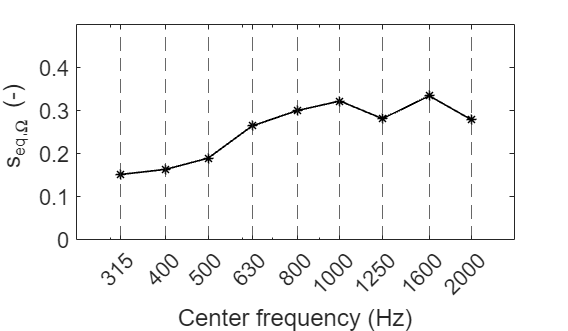

figure;
plot(centerFrequenciesValid, ESC, "k*-", 'LineWidth', 1)
for iOctaveBand = 1:nOctaveBands
    hold on
    xline(centerFrequenciesValid(iOctaveBand), '--')
end
set(gca,'YLim',[0 0.5]);
set(gca,'XLim',[250 2500]);
set(gca,'XScale','log');
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');
ylabel(' s_{eq,\Omega} (-)');
set(gca, 'FontSize', 13);
set(gcf, 'Units', 'centimeters', 'Position', [10, 10, 12, 7]);

#### Plot coherence coefficent curves

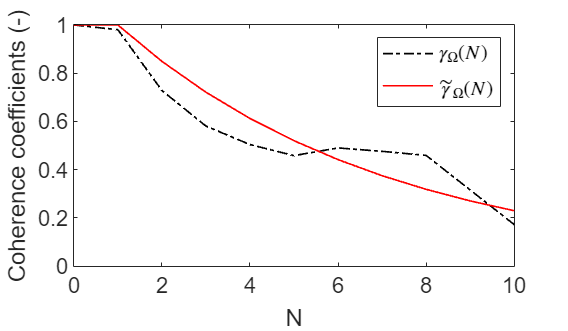

figure;
plot(nOrder,coherenceCoefs(plotOctaveBand,:),"k-.",'LineWidth',1);
hold on;
plot(nOrder,predictedCoherenceCurve(plotOctaveBand,:),"r",'LineWidth',1);
set(gca,'YLim',[0 1]);
set(gca,'XLim',[0 maxOrder]);
legend({'$\gamma_{\Omega}(N)$','$\tilde{\gamma}_{\Omega}(N)$'}, 'Interpreter', 'latex');
xlabel('N');ylabel('Coherence coefficients (-)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);

#### Reverberation time and decay curve for 1/3 octave bands

for iScenario = 1:nScenarios
for iReceiver = 1:nReceivers
    nStart=nDirectSample(iReceiver);
for iOctaveBand = 1:nOctaveBands
 [thisEDT,thisT20,thisT30,thisDecayCurve] = calculate_reverbtime(nStart, IRfiltered(iScenario,iReceiver,iOctaveBand,:), nSamplesSignal,tv);
EDT(iScenario,iReceiver,iOctaveBand,:)=thisEDT;
T20(iScenario,iReceiver,iOctaveBand,:)=thisT20;
T30(iScenario,iReceiver,iOctaveBand,:)=thisT30;
decayCurves(iScenario,iReceiver,iOctaveBand,:)=thisDecayCurve;
end
end
end
% Spatial averaged values
averagedDecayCurves=reshape(mean(decayCurves,2),nScenarios,nOctaveBands,[]);
averagedEDT=reshape(mean(EDT,2),nScenarios,nOctaveBands);
averagedT20=reshape(mean(T20,2),nScenarios,nOctaveBands);
averagedT30=reshape(mean(T30,2),nScenarios,nOctaveBands);

#### Max magnitude of the IRs

for iScenario = 1:nScenarios
for iReceiver = 1:nReceivers
    nStart=nDirectSample(iReceiver);
 [~,~,thisWideBandT30,thisWideBandDecayCurve] = calculate_reverbtime(nStart, IRsWideBand(iScenario,iReceiver,:), nSamplesSignal,tv);
% Decay curve for wide band IRs
wideBandDecayCurves(iScenario,iReceiver,:)=thisWideBandDecayCurve;
% Wide band reverberation time
wideBandT30(iScenario,iReceiver,:)=thisWideBandT30;
end
end
% Spatial averaged value
averagedWideBandDecayCurves=reshape(mean(wideBandDecayCurves,2),2,[]);
% Strength that related to source power
wideBandMaxMagnitude=10^((averagedWideBandDecayCurves(1,1)-120)/20);
% Correction according to the energy of filters
filterMaxMagnitudeCorrection=(sum((abs(bandpassFiltersValid)).^2)/sum(sum((abs(bandpassFiltersValid)).^2))).^0.5;
% Max magnitude for each 1/3 octave band
maxMagnitude=wideBandMaxMagnitude.*filterMaxMagnitudeCorrection;

#### Index for sound pressure level decrease 60 dB

averagedwideBandT30=mean(wideBandT30,2)

averagedwideBandT30 =     0.6489
    0.4370


n60dB=floor(averagedwideBandT30*fs);

#### Schroeder frequency (Hz)

schroederFrequency = (0.33 * (averagedwideBandT30(1) * c0.^3 / volume).^0.5);

#### Absorption envelope

for iScenario = 1:nScenarios
for iOctaveBand=1:nOctaveBands
thisaveragedDecayCurves=reshape(averagedDecayCurves(iScenario,iOctaveBand,:),1,[]);
% 6 points used for interpolation
pDecay(1)=spl(maxMagnitude(iOctaveBand));
pDecay(2)=thisaveragedDecayCurves((nSamplesSignal-1)/5);
pDecay(3)=thisaveragedDecayCurves(2*(nSamplesSignal-1)/5);
pDecay(4)=thisaveragedDecayCurves(3*(nSamplesSignal-1)/5);
pDecay(5)=thisaveragedDecayCurves(4*(nSamplesSignal-1)/5);
pDecay(6)=thisaveragedDecayCurves(nSamplesSignal);
% Index for these points
pIndex=[1,(nSamplesSignal-1)/5,2*(nSamplesSignal-1)/5,3*(nSamplesSignal-1)/5,4*(nSamplesSignal-1)/5,nSamplesSignal];
% 1-D interpolation
thisDecayCurvesFitted=10.^((interp1(pIndex,pDecay,1:nSamplesSignal)-120)/20);
% Absorption Envelope
absorptionEnvelope(iScenario,iOctaveBand,:)=thisDecayCurvesFitted;
end
end
% Absorption correction
absorptionCorrection=reshape(absorptionEnvelope(2,:,:)./absorptionEnvelope(1,:,:),nOctaveBands,[]);

#### Plot IR and absorption envelope

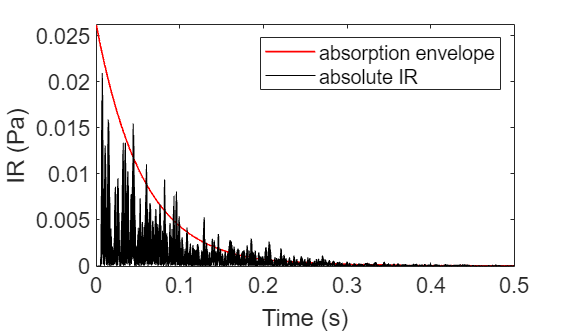

figure;
plot(tv,reshape(absorptionEnvelope(2,plotOctaveBand,:),1,[]),"r",'LineWidth',1);
hold on;
plot(tv,abs(reshape(IRfiltered(1,plotReceiver,plotOctaveBand,:),1,[])),"k",'LineWidth',0.1);
set(gca,'XLim',[0 0.5]);
set(gca,'YLim',[0 maxMagnitude(plotOctaveBand)]);
legend('absorption envelope','absolute IR')
xlabel('Time (s)');ylabel('IR (Pa)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7])

#### Plot absorption envelopes of empty room and furnished room                  [FIG.10(a)]

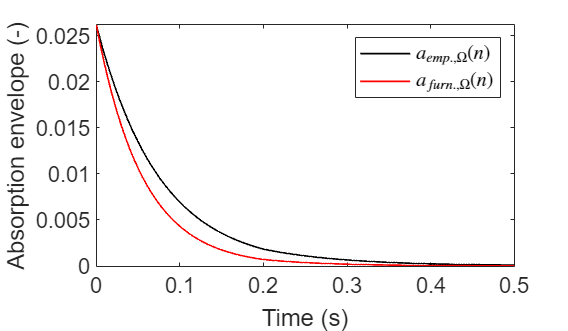

figure
plot(tv,reshape(absorptionEnvelope(1,plotOctaveBand,:),1,[]),"k",'LineWidth',1);
hold on
plot(tv,reshape(absorptionEnvelope(2,plotOctaveBand,:),1,[]),"r",'LineWidth',1);
set(gca,'YLim',[0 maxMagnitude(plotOctaveBand)]);
set(gca,'XLim',[0 0.5]);
legend('${a}_{emp.,\Omega}(n)$','${a}_{furn.,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Absorption envelope (-)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7])

#### Specular and non-specular envelopes

specularEnvelope = coherentEnvelope.* reshape(absorptionEnvelope(2,:,:),nOctaveBands,[]);
nonspecularEnvelope = incoherentEnvelope.* reshape(absorptionEnvelope(2,:,:),nOctaveBands,[]);

#### Plot specular and non-specular envelopes             [FIG.10(b)]

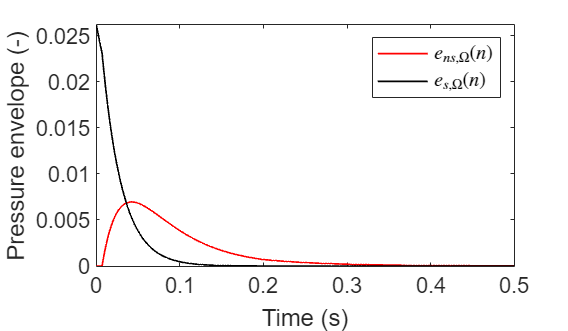

figure;
plot(tv,nonspecularEnvelope(plotOctaveBand,:),"r",'LineWidth',1)
hold on
plot(tv,specularEnvelope(plotOctaveBand,:),"k",'LineWidth',1)
legend('${e}_{ns,\Omega}(n)$','${e}_{s,\Omega}(n)$', 'Interpreter', 'latex')
set(gca,'YLim',[0 maxMagnitude(plotOctaveBand)]);
set(gca,'XLim',[0 0.5]);
xlabel('Time (s)');ylabel('Pressure envelope (-)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);

## Hybrid model

for iReceiver = 1:nReceivers
for iOctaveBand = 1:nOctaveBands
%  IRs of empty room corrected by absorption 
IRfilteredEmptyCorrected =reshape(IRfiltered(1,iReceiver,iOctaveBand,:),1,[]).*absorptionCorrection(iOctaveBand,:);
%  IRs of furnished room
IRfilteredFurnished = reshape(IRfiltered(2,iReceiver,iOctaveBand,:),1,[]);
% Specular part
thisSpecularPart = IRfilteredEmptyCorrected .* coherentEnvelope(iOctaveBand,:);
% Non-specular part generated by noise
noise = (2 * rand(1, nSamplesSignal) - 1);
noiseFiltered=calculate_filteredSignal(noise',bandpassFiltersValid(:,iOctaveBand),nSamplesSignal);
thisNoiseCorrection = ((sum((abs(noise)).^2) / sum((abs(noiseFiltered)).^2)))^0.5;
thisNoiseFilteredCorrected = thisNoiseCorrection * noiseFiltered;
thisNonSpecularPartPredicted = (thisNoiseFilteredCorrected' .* nonspecularEnvelope(iOctaveBand,:));
%  Predicted Furnished room IRs
thisIRfilteredPredicted = thisNonSpecularPartPredicted + thisSpecularPart;

%  Store data in matrix
specularPart(iReceiver,iOctaveBand, :)=thisSpecularPart;
nonspecularPartTruth(iReceiver,iOctaveBand, :)=IRfilteredFurnished - thisSpecularPart;
nonspecularPartPredicted(iReceiver,iOctaveBand, :)=thisNonSpecularPartPredicted;
IRfilteredFurnishedPredicted(iReceiver,iOctaveBand, :)=thisIRfilteredPredicted;
end
end

#### Plot specular part             [FIG.10(c)]

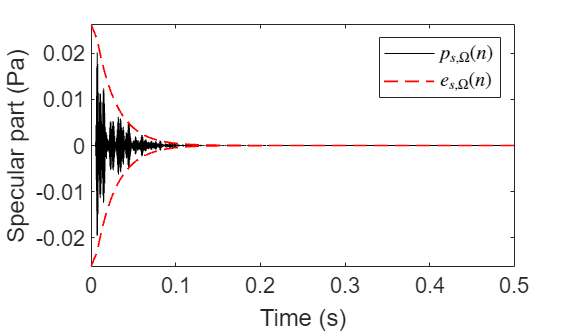

figure;
plot(tv,reshape(specularPart(plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.1);
hold on
plot(tv,specularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
hold on
plot(tv,-specularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
legend('${{p}_{s,\Omega}}(n)$','${e}_{s,\Omega}(n)$', 'Interpreter', 'latex')
set(gca,'YLim',[-maxMagnitude(plotOctaveBand) maxMagnitude(plotOctaveBand)]);
set(gca,'XLim',[0 0.5]);
xlabel('Time (s)');ylabel('Specular part (Pa)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);

#### Plot real non-specular part 

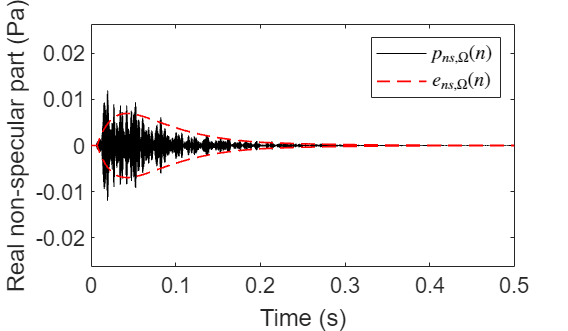

figure;
plot(tv,reshape(nonspecularPartTruth(plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.1);
hold on
plot(tv,nonspecularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
hold on
plot(tv,-nonspecularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
legend('${{p}_{ns,\Omega}}(n)$','${e}_{ns,\Omega}(n)$', 'Interpreter', 'latex')
set(gca,'YLim',[-maxMagnitude(plotOctaveBand) maxMagnitude(plotOctaveBand)]);
set(gca,'XLim',[0 0.5]);
xlabel('Time (s)');ylabel('Real non-specular part (Pa)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);

#### Plot generated non-specular part         [FIG.10(d)]

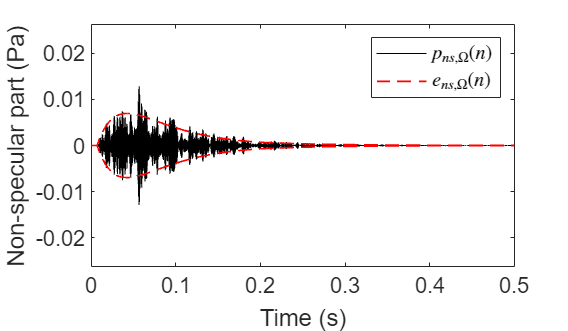

figure;
plot(tv,reshape(nonspecularPartPredicted(plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.1);
hold on
plot(tv,nonspecularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
hold on
plot(tv,-nonspecularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
legend('${{p}_{ns,\Omega}}(n)$','${e}_{ns,\Omega}(n)$', 'Interpreter', 'latex')
set(gca,'YLim',[-maxMagnitude(plotOctaveBand) maxMagnitude(plotOctaveBand)]);
set(gca,'XLim',[0 0.5]);
xlabel('Time (s)');ylabel('Non-specular part (Pa)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);

#### Plot IR (Pa) of 1/3 octave bands                [FIG.4]

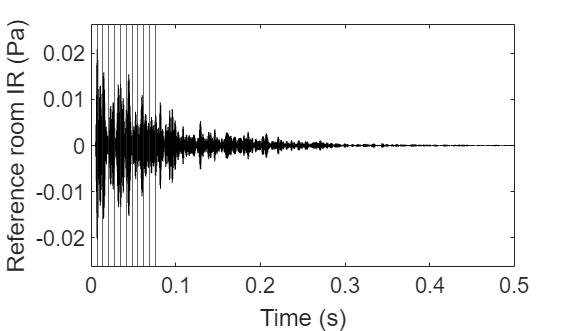

% IR of empty room
figure;
for iSegment=1:maxOrder+1
    hold on
    xline(iSegment*nChoppedIR/fs,'LineWidth',0.3)
end
plot(tv,reshape(IRfiltered(1,plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.1);
set(gca,'YLim',[-maxMagnitude(plotOctaveBand) maxMagnitude(plotOctaveBand)]);
set(gca,'XLim',[0 0.5]);
xlabel('Time (s)');ylabel( 'Reference room IR (Pa)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);
box on

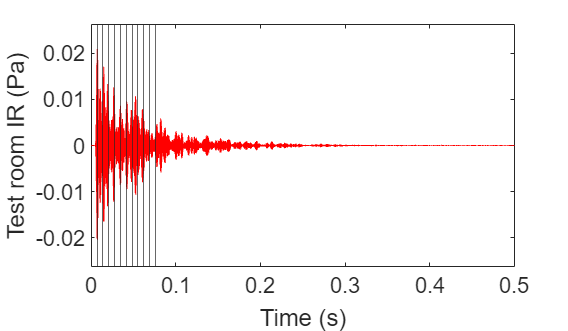

% Ground truth IR of furnished room
figure;
for iSegment=1:maxOrder+1
    hold on
    xline(iSegment*nChoppedIR/fs,'LineWidth',0.3)
end
hold on
plot(tv,reshape(IRfiltered(2,plotReceiver,plotOctaveBand,:),1,[]),"r",'LineWidth',0.1);
set(gca,'YLim',[-maxMagnitude(plotOctaveBand) maxMagnitude(plotOctaveBand)]);
set(gca,'XLim',[0 0.5]);
xlabel('Time (s)');ylabel( 'Test room IR (Pa)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);
box on

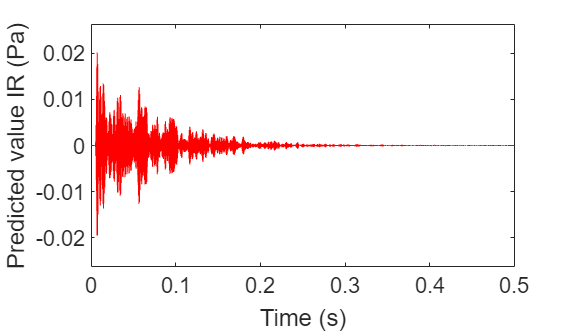

% Predicted IR of furnished room
figure;
plot(tv,reshape(IRfilteredFurnishedPredicted(plotReceiver,plotOctaveBand,:),1,[]),"r",'LineWidth',0.1);
set(gca,'YLim',[-maxMagnitude(plotOctaveBand) maxMagnitude(plotOctaveBand)]);
set(gca,'XLim',[0 0.5]);
xlabel('Time (s)');ylabel('Predicted value IR (Pa)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);
box on

#### Plot IR (dB) of 1/3 octave bands              [FIG.11]

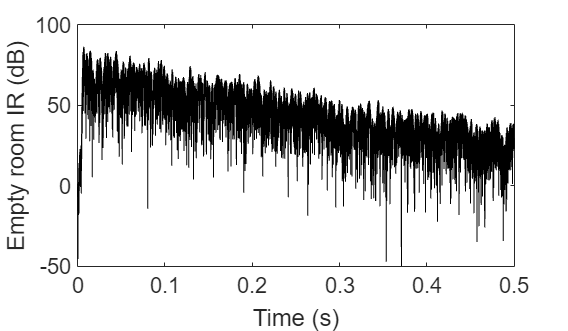

%  IR of reference room
figure;
plot(tv,spl(reshape(IRfiltered(1,plotReceiver,plotOctaveBand,:),1,[])),"k",'LineWidth',0.1);
set(gca,'YLim',[-50 100]);
set(gca,'XLim',[0 0.5]);
xlabel('Time (s)');ylabel('Empty room IR (dB)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);

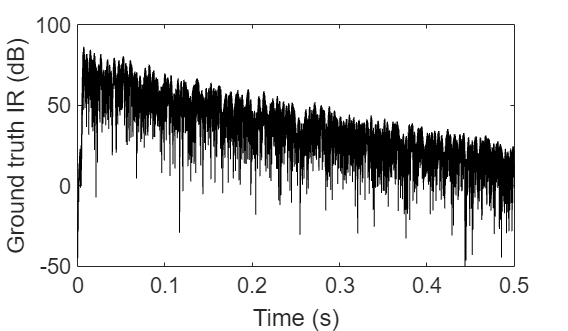

% Ground truth IR of furnished room
figure;
plot(tv,spl(reshape(IRfiltered(2,plotReceiver,plotOctaveBand,:),1,[])),"k",'LineWidth',0.1);
set(gca,'YLim',[-50 100]);
set(gca,'XLim',[0 0.5]);
xlabel('Time (s)');ylabel('Ground truth IR (dB)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);

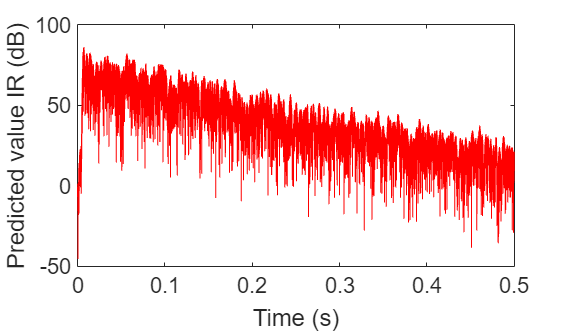

% Predicted IR of furnished room
figure
plot(tv,spl(reshape(IRfilteredFurnishedPredicted(plotReceiver,plotOctaveBand,:),1,[])),"r",'LineWidth',0.1);
set(gca,'YLim',[-50 100]);
set(gca,'XLim',[0 0.5]);
xlabel('Time (s)');ylabel('Predicted value IR (dB)');
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);

## Evaluation

for iReceiver = 1:nReceivers
% Index for direct sound
nStart=nDirectSample(iReceiver);
for iOctaveBand = 1:nOctaveBands
% Ground truth IR
thisIRfilteredFurnishedTruth = reshape(IRfiltered(2,iReceiver,iOctaveBand,:),1,[]);
[thisEDTTruth,thisT20Truth,thisT30Truth,thisDecayCurveTruth] = calculate_reverbtime(nStart, thisIRfilteredFurnishedTruth, nSamplesSignal,tv);
thisEnergyTruth=calculate_energy(thisIRfilteredFurnishedTruth(1:n60dB));
% Store data in matrix
EDTTruth(iReceiver,iOctaveBand,:)=thisEDTTruth;
T20Truth(iReceiver,iOctaveBand,:)=thisT20Truth;
T30Truth(iReceiver,iOctaveBand,:)=thisT30Truth;
EnergyTruth(iReceiver,iOctaveBand,:)=thisEnergyTruth;
DecayCurveTruth(iReceiver,iOctaveBand,:)=thisDecayCurveTruth;
% Predicted IR
thisIRfilteredPredicted=reshape(IRfilteredFurnishedPredicted(iReceiver,iOctaveBand,:),1,[]);
[thisEDTPredicted,thisT20Predicted,thisT30Predicted,thisDecayCurvePredicted] = calculate_reverbtime(nStart, thisIRfilteredPredicted, nSamplesSignal,tv);
thisEnergyPredicted=calculate_energy(thisIRfilteredPredicted(1:n60dB));
% Store data in matrix
EDTPredicted(iReceiver,iOctaveBand,:)=thisEDTPredicted;
T20Predicted(iReceiver,iOctaveBand,:)=thisT20Predicted;
T30Predicted(iReceiver,iOctaveBand,:)=thisT30Predicted;
EnergyPredicted(iReceiver,iOctaveBand,:)=thisEnergyPredicted;
DecayCurvePredicted(iReceiver,iOctaveBand,:)=thisDecayCurvePredicted;
end
end
% Percentage error of the spatial averaged EDT, T20, T30
errorEDT=abs((mean(EDTPredicted)-mean(EDTTruth))./mean(EDTTruth))*100;
errorT20=abs((mean(T20Predicted)-mean(T20Truth))./mean(T20Truth))*100;
errorT30=abs((mean(T30Predicted)-mean(T30Truth))./mean(T30Truth))*100;

#### Plot error bar in 1/3 octave band         [FIG.12]

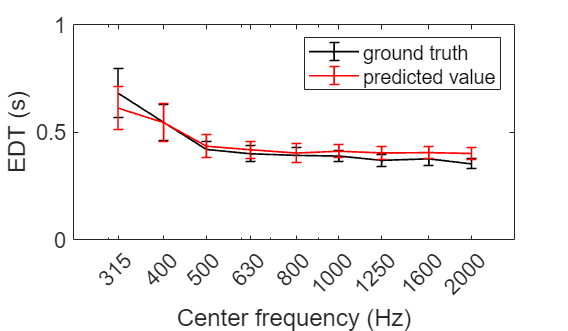

figure;
errorbar(centerFrequenciesValid,mean(EDTTruth),std(EDTTruth), "k-", 'LineWidth', 1)
hold on
errorbar(centerFrequenciesValid,mean(EDTPredicted),std(EDTPredicted), "r-", 'LineWidth', 1)
set(gca,'XLim',[250 2500]);
set(gca,'YLim',[0 1]);
set(gca,'XScale','log');
legend('ground truth','predicted value')
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');
ylabel('EDT (s)');
set(gca, 'FontSize', 13);
set(gcf, 'Units', 'centimeters', 'Position', [10, 10, 12, 7]);

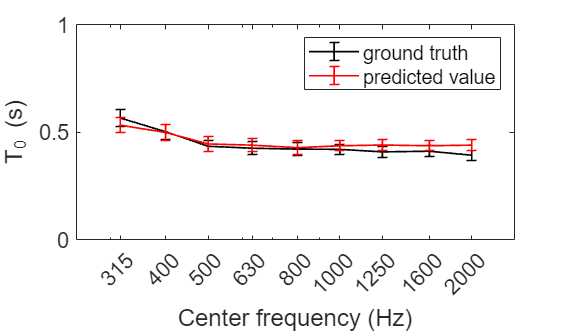

figure;
errorbar(centerFrequenciesValid,mean(T20Truth),std(T20Truth), "k-", 'LineWidth', 1)
hold on
errorbar(centerFrequenciesValid,mean(T20Predicted),std(T20Predicted), "r-", 'LineWidth', 1)
set(gca,'XLim',[250 2500]);
set(gca,'YLim',[0 1]);
set(gca,'XScale','log');
legend('ground truth','predicted value')
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');
ylabel('T_2_0 (s)');
set(gca, 'FontSize', 13);
set(gcf, 'Units', 'centimeters', 'Position', [10, 10, 12, 7]);

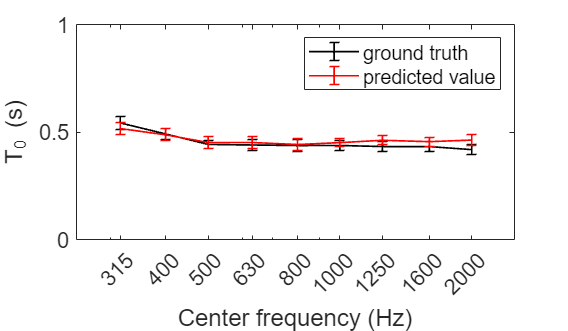

figure;
errorbar(centerFrequenciesValid,mean(T30Truth),std(T30Truth), "k-", 'LineWidth', 1)
hold on
errorbar(centerFrequenciesValid,mean(T30Predicted),std(T30Predicted), "r-", 'LineWidth', 1)
set(gca,'XLim',[250 2500]);
set(gca,'YLim',[0 1]);
set(gca,'XScale','log');
legend('ground truth','predicted value')
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');
ylabel('T_3_0 (s)');
set(gca, 'FontSize', 13);
set(gcf, 'Units', 'centimeters', 'Position', [10, 10, 12, 7]);

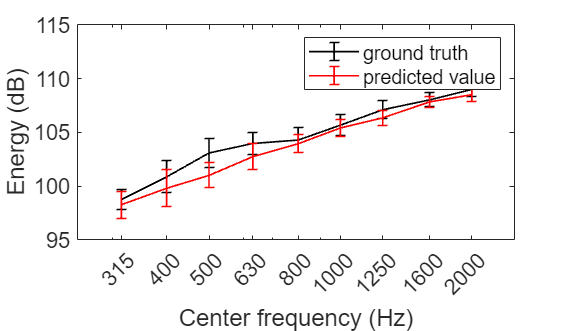

figure;
errorbar(centerFrequenciesValid,mean(EnergyTruth),std(EnergyTruth), "k-", 'LineWidth', 1)
hold on
errorbar(centerFrequenciesValid,mean(EnergyPredicted),std(EnergyPredicted), "r-", 'LineWidth', 1)
set(gca,'XLim',[250 2500]);
set(gca,'YLim',[95 115]);
set(gca,'XScale','log');
legend('ground truth','predicted value')
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');
ylabel('Energy (dB)');
set(gca, 'FontSize', 13);
set(gcf, 'Units', 'centimeters', 'Position', [10, 10, 12, 7]);

## To check scattering degree in the predicted sound field

#### To calculate ESCs

% Empty room IRs
IRfiltered_P(1,:,:,:)=IRfiltered(1,:,:,:);
% Predicted furnished room IRs
IRfiltered_P(2,:,:,:)=IRfilteredFurnishedPredicted;
% To calculate ESCs
[ESC_P] = calculate_ESC(fs,maxOrder,nOrder,nScenarios,nReceivers,nOctaveBands,nChoppedIR,nFrequency,IRfiltered_P);

####  Plot ESC     [FIG.13]

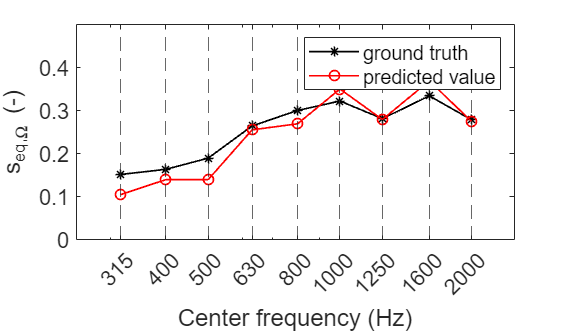

figure;
plot(centerFrequenciesValid, ESC, "k*-", 'LineWidth', 1)
hold on
plot(centerFrequenciesValid, ESC_P, "ro-", 'LineWidth', 1)
for iOctaveBand = 1:nOctaveBands
    hold on
    xline(centerFrequenciesValid(iOctaveBand), '--')
end
legend('ground truth','predicted value')
set(gca,'YLim',[0 0.5]);
set(gca,'XLim',[250 2500]);
set(gca,'XScale','log');
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');
ylabel('s_{eq,\Omega} (-)');
set(gca, 'FontSize', 13);
set(gcf, 'Units', 'centimeters', 'Position', [10, 10, 12, 7]);

## Plane wave density function analysis

% Wide band predicted IRs
IRsWideBandFurnished(1,:,:)=IRsWideBand(2,:,:);
% Wide band predicted IRs
IRsWideBandFurnished(2,:,:)=reshape(sum(IRfilteredFurnishedPredicted,2),1,nReceivers,nSamplesSignal);
% Two scenrios (i) ground truth (ii) predicted value
nScenariosFurnished=size(IRsWideBandFurnished,1);
% Remove direct sound (for the first mean free path length IR=0)
IRsWideBandFurnished(:,:,1:nChoppedIR)=zeros(2,nReceivers,nChoppedIR);
% Fourier Transform of the frequency spectrums
STFsWideBand=fft(IRsWideBandFurnished,[],3)/nSamplesSignal;% symmetric transfer function
TFsWideBand=STFsWideBand(:,:,1:fMax+1);% single side transfer function


#### Parameters of spherical receiver array

% Radius of the sphere
rm=0.2;
% Order of spherical harmonics
N_s=6;
% Uniform_sampling method
[~,th_s,ph_s]=uniform_sampling(N_s);
% Spherical harmonic function
Ys=sh2(N_s,th_s,ph_s).'; 
% Open sphere 
sphere=0;

#### Parameters of plane waves

% Order of spherical harmonics
N_bar=6;
% Directions
N_q=51;
th_q_p=0:pi/(N_q-1):pi;
ph_q_p=0:pi/(N_q-1):2*pi;
[phi_q,theta_q]=meshgrid(ph_q_p,th_q_p);
ph_q=reshape(phi_q,1,[]);
th_q=reshape(theta_q,1,[]);
% Spherical harmonic function
Yq=sh2(N_bar,th_q,ph_q).'; 

#### Plane wave decomposition

for iScenario = 1:nScenariosFurnished
for iFrequency=1:fMax+1
% Wave number
k=2*pi*(iFrequency-1)/c0;
kr=k*rm;
% Radial functions
B=diag(BnMat(N_bar,kr,kr,sphere));
% Sound field distribution on the sphere at this frequency
soundField=reshape(TFsWideBand(iScenario,:,iFrequency),[],1);
% Spherical harmonics coeffcients
thisPnm=(B*Ys')*soundField;  
% Plane wave density function
thisPWD=reshape(Yq*thisPnm,N_q,2*(N_q-1)+1);
PWD(iScenario,iFrequency,:,:)=thisPWD;
end
end


#### To average over 1/3 octave bands

for iScenario=1:nScenariosFurnished
for iOctaveBand=1:nOctaveBands
% 1/3 octave bands filter
PWDFiltered=abs(reshape(PWD(iScenario,:,:,:),[],N_q,2*(N_q-1)+1).*bandpassFiltersValid(1:fMax+1,iOctaveBand)).^2;
% Average over each band and normalize it 
PWDOctaveBand(:,:,iOctaveBand,iScenario)=abs(reshape(mean(PWDFiltered,1).^0.5,N_q,2*(N_q-1)+1))./max(max(abs(reshape(mean(PWDFiltered,1).^0.5,N_q,2*(N_q-1)+1))));
end
end



#### Plot PWDs   [FIG.14 (a) and FIG.14 (b)]

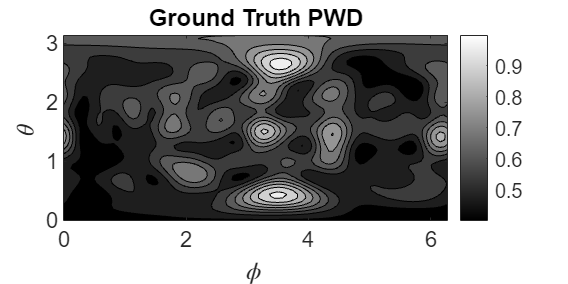

% Ground truth PWD
figure
ValLines=(min(min(PWDOctaveBand(:,:,plotOctaveBand,1)))-0.07):0.07:1;
[C,h]=contourf(ph_q_p,th_q_p,PWDOctaveBand(:,:,plotOctaveBand,1),ValLines);
caxis([min(min(PWDOctaveBand(:,:,plotOctaveBand,1))),1]);
colormap(gray);
colorbar;
title('Ground Truth PWD');
xlabel('$\phi\,$','Interp','Latex');  
ylabel('$\theta\,$','Interp','Latex'); 
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 6]);

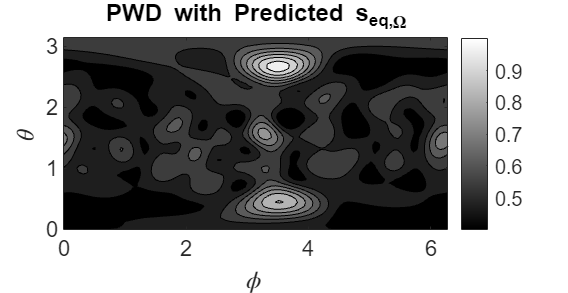

% Predicted PWD
figure
[C,h]=contourf(ph_q_p,th_q_p,PWDOctaveBand(:,:,plotOctaveBand,2),ValLines);
caxis([min(min(PWDOctaveBand(:,:,plotOctaveBand,1))),1]);
colormap(gray);
colorbar;
title('PWD with Predicted s_{eq,\Omega}');
xlabel('$\phi\,$','Interp','Latex');  
ylabel('$\theta\,$','Interp','Latex'); 
set(gca,'FontSize',13);
set(gcf,'Units','centimeters','Position',[10 10 12 6.2]);

#### Coherence coefficients of ground truth PWD and predicted PWD

Fx=reshape(PWD(1,:,:,:),2501,[]);
Fy=reshape(PWD(2,:,:,:),2501,[]);
Sxx = (abs(Fx)).^2;
Syy = (abs(Fy)).^2;
Sxy = Fx .* conj(Fy);
SXX = abs(mean(Sxx, 2));
SYY = abs(mean(Syy, 2));
SXY = abs(mean(Sxy, 2));
% Coherence coefficients of single frequency
coherenceCoefsPWD_thisFrequency = SXY./((SXX .* SYY).^0.5);
% Coherence coefficients averaged over 1/3 octave band
for iOctaveBand=1:nOctaveBands
coherenceCoefsPWD(iOctaveBand)=mean(coherenceCoefsPWD_thisFrequency(BandedgeFrequenciesValid(iOctaveBand):BandedgeFrequenciesValid(iOctaveBand+1)));
end

#### Plot coherence coefficients

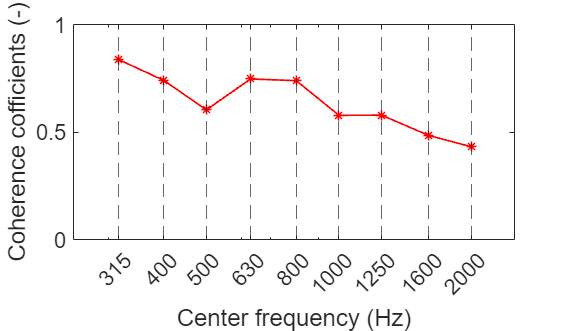

figure;
plot(centerFrequenciesValid, coherenceCoefsPWD,"r*-",'LineWidth',1)
for iOctaveBand = 1:nOctaveBands
    hold on
    xline(centerFrequenciesValid(iOctaveBand), '--')
end
set(gca,'YLim',[0 1]);
set(gca,'XLim',[250 2500]);
set(gca,'XScale','log');
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');
ylabel('Coherence cofficients (-)');
set(gca, 'FontSize', 13);
set(gcf,'Units','centimeters','Position',[10 10 12 7]);